# Visualizing the Data from Protocol1

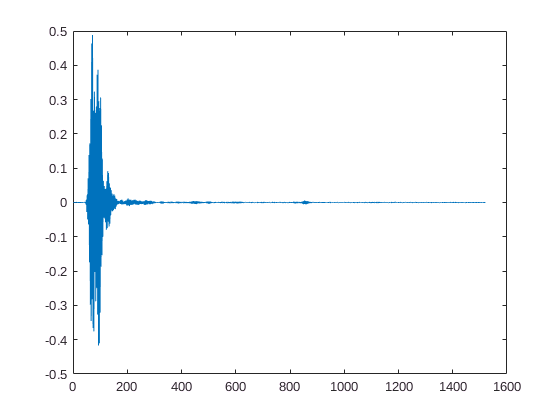

%You need to be in the '7-11-2017 Protocol1' folder

%Folder can be "baseline" or "chicken5x4x1cm" or "screw-2mm-0.8cm" or "screw-3mm-1.2cm" or "screw-3mm-1.5cm"
folder = 'baseline';

height = '15.5cm';

%Frequency can be...
    %2 (5.832 GHz)
    %3 (7.29 GHz))
    %4 (8.748 GHz)
    %5 (10.206 GHz)
frequency = '3';

%Specify the dacmin and dacmax values (default: dacmin = 949, dacmax = 1100)
dacmin = '100';
dacmax = '1400';

%Specify whether to plot the baseband or rf data"
mode = 'rf';

%Specify which of the 5 fast time sequences
fts = 1;

%Load the data
table_name = strcat(mode,dacmin,'_',dacmax,'f',frequency);
S = load(strcat(folder,'/',height,'.mat'));
data = S.(table_name);

%Draw the plots (loop through the folder)
if (strcmp(mode,'bb'))
    plot(abs(data(fts,:)));
else
    plot((data(fts,:)));   
end